# Inverted Cart Pendulum

## 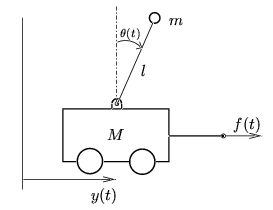


$$\vec{x} = \pmatrix{\bf{q} \cr \bf{\dot{q}} } \quad 
@ \quad q = \pmatrix{y \cr \theta} \enspace \& \enspace
\dot{q} = \pmatrix{\dot y \cr \dot \theta}$$


[Link](https://www.mathworks.com/help/symbolic/simulate-physics-pendulum-swing.html)

see MATLAB for **Solve Differential Algebraic Equations (DAEs)**

**see **[YouTube](https://www.youtube.com/watch?v=hAI8Ag3bzeE&t=210s)** video**

**Setup Symbolics**

clearvars;
syms m l t M g F real positive
syms q [2 1] real
syms qd [2 1] real
syms qdd [2 1] real
syms y(t) theta(t) v(t) omega(t)

state = [q;qd];
dstate = [qd;qdd];

**Masses - position and velocity**

rPend = [q1 + l*sin(q2);l*cos(q2)];
vPend = jacobian(rPend, q)*qd;
rCart = [q1;0];
vCart = jacobian(rCart, q)*qd;

**Kinetic and Potential Energy of system (m and M)**

T = 1/2*M*(vCart.'*vCart) + 1/2*m*(vPend.' * vPend);
V = m*rPend.' * [0;g];
u = [F;0];
L = T - V;

**Deriving eom`s in generalized coordinates**


$$\frac{d}{dt}\Big( \frac{\partial T}{\partial \dot q} \Big) -\frac{\partial T}{\partial q}  +  \frac{\partial V}{\partial q}=\Sigma F \\
L \equiv E_k - E_p$$


dT_dq = gradient(T,q);
dV_dq = gradient(V,q);
dT_dqd = gradient(T, qd);
ddt_dT_dqd = jacobian(dT_dqd, q)*qd + jacobian(dT_dqd, qd)*qdd;

eqns = simplify(ddt_dT_dqd - dT_dq + dV_dq) == u

$$eqns = \left[\begin{array}{c} -l\,m\,\sin\left(q_{2}\right)\,{{\mathrm{qd}}_{2}}^{2}+{\mathrm{qdd}}_{1}\,\left(M+m\right)+l\,m\,{\mathrm{qdd}}_{2}\,\cos\left(q_{2}\right)=F\\ l\,m\,\left(l\,{\mathrm{qdd}}_{2}+{\mathrm{qdd}}_{1}\,\cos\left(q_{2}\right)-g\,\sin\left(q_{2}\right)\right)=0 \end{array}\right]$$

**Reducing order**

qdd_expr = solve(eqns, qdd);
fnames = fieldnames(qdd_expr);
dstate_expr = qd;

for ind = 1 : numel(fnames)
    dstate_expr(ind+2,1) = qdd_expr.(char(fnames(ind)));
end

**Linearization**

1st fixed point - pendulum looking up

fixedPnt_up = zeros(4,1);
A_up = simplify(subs(jacobian(dstate_expr, state), state, fixedPnt_up))

$$A\_up = \left[\begin{array}{cccc} 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1\\ 0 & -\frac{g\,m}{M} & 0 & 0\\ 0 & \frac{g\,\left(M+m\right)}{M\,l} & 0 & 0 \end{array}\right]$$

B_up = simplify(subs(jacobian(dstate_expr, u(u~=0)), state, fixedPnt_up))

$$B\_up = \left[\begin{array}{c} 0\\ 0\\ \frac{1}{M}\\ -\frac{1}{M\,l} \end{array}\right]$$

2nd point - pendulum looking down

fixedPnt_dwn = [0;pi;0;0];
A_dwn = simplify(subs(jacobian(dstate_expr, state), state, fixedPnt_dwn))

$$A\_dwn = \left[\begin{array}{cccc} 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1\\ 0 & -\frac{g\,m}{M} & 0 & 0\\ 0 & -\frac{g\,\left(M+m\right)}{M\,l} & 0 & 0 \end{array}\right]$$

B_dwn = simplify(subs(jacobian(dstate_expr, u(u~=0)), state, fixedPnt_dwn))

$$B\_dwn = \left[\begin{array}{c} 0\\ 0\\ \frac{1}{M}\\ \frac{1}{M\,l} \end{array}\right]$$

## Simulation

**Define free Parameters**

extraParams = union(symvar(A_up), symvar(B_up))

$$extraParams = \left(\begin{array}{cccc} M & g & l & m \end{array}\right)$$

M_val = 0.1;
g_val = 9.81;
l_val = 3;
m_val = 0.3;

extraParamsVals = [M_val g_val l_val m_val];


**Going Numeric**

1st point

A_up_num = eval(subs(A_up, extraParams, extraParamsVals));
B_up_num = eval(subs(B_up, extraParams, extraParamsVals));
C_num = eye(size(A_up_num));
D_num = zeros(size(B_up_num));

sys_up = ss(A_up_num, B_up_num, C_num, D_num);

2nd point

A_dwn_num = eval(subs(A_dwn, extraParams, extraParamsVals));
B_dwn_num = eval(subs(B_dwn, extraParams, extraParamsVals));
sys_dwn = ss(A_dwn_num, B_dwn_num, C_num, D_num);

**Simulating**

iCond = [0.0; pi/8; 0.0; 0.0];
tInit = 0;
tFinal = 10;
tSpan = [tInit:0.01:tFinal]';
u_val = zeros(size(tSpan));

[sol_up, t_up] = initial(sys_up, iCond, tFinal);
[sol_dwn, t_dwn] = initial(sys_dwn, iCond, tFinal);

**Visualization**

system up - unstable

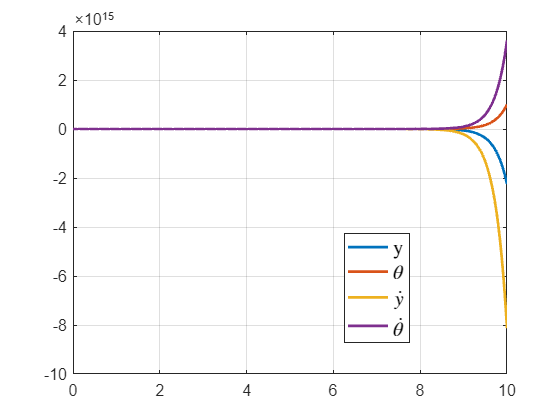

figure
plot(t_up, sol_up, 'LineWidth',2), hold on

legend({'y', '$\theta$', '$\dot{y}$', '$\dot{\theta}$'}, 'Location',"best", 'Interpreter',"latex", "FontSize",15)
grid on

system down - stable

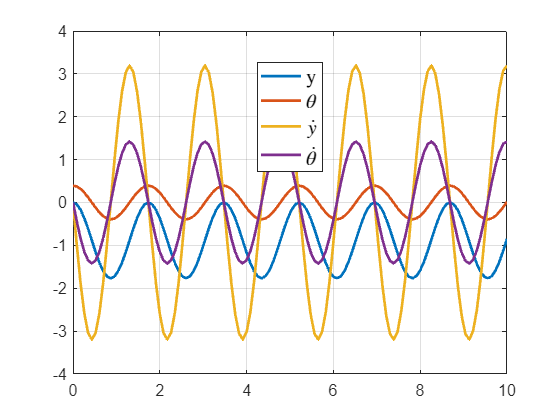

figure
plot(t_dwn, sol_dwn, 'LineWidth',2), hold on

legend({'y', '$\theta$', '$\dot{y}$', '$\dot{\theta}$'}, 'Location',"best", 'Interpreter',"latex", "FontSize",15)
grid on

**Animation**

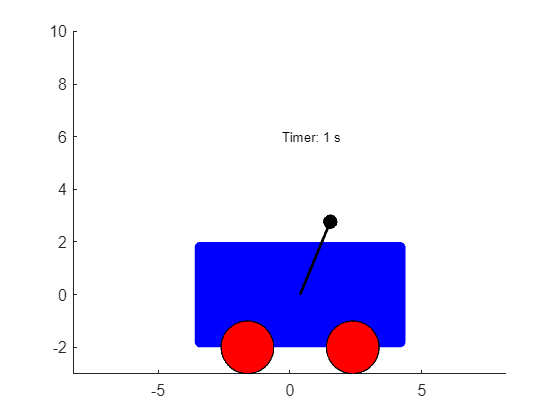

y_pos_cart = @(t) sin(sol_dwn(t,2));
y_pos_pend = @(t) y_pos_cart(t) + l_val*sin(sol_dwn(t,2));
z_pos_pend = @(t) l_val*cos(sol_dwn(t,2));

Hcart = 4;
Wcart = 8;
wSize = 2;
pSize = 0.5;

r = @(t) rectangle('Position',[y_pos_cart(t)-Wcart/2 -Hcart/2 Wcart Hcart ], 'Curvature', 0.1, 'FaceColor', [0 0 1 0.3], "EdgeColor",'none');
w1 = @(t) rectangle('Position',[y_pos_cart(t)-Wcart/4-wSize/2 -Hcart/2-wSize/2 wSize wSize ], 'Curvature', 1.0, "FaceColor",'r');
w2 = @(t) rectangle('Position',[y_pos_cart(t)+Wcart/4-wSize/2 -Hcart/2-wSize/2 wSize wSize ], 'Curvature', 1.0, "FaceColor",'r');
pend = @(t) rectangle('Position', [y_pos_pend(t)-pSize/2  z_pos_pend(t)-pSize/2 pSize  pSize],"Curvature",1.0, "FaceColor",'k');
pendRod = @(t) line([y_pos_cart(t) y_pos_pend(t)],[0 z_pos_pend(t)],'Color','k', 'LineWidth', 2);
txt = @(t) text(-0.3,6.0,"Timer: "+num2str(t,2)+" s");

figure;
axis equal
ylim([-Hcart/2-wSize/2 10])
hold on
fanimator(r, 'AnimationRange',[1 numel(t_dwn)],'FrameRate',1);
fanimator(w1, 'AnimationRange',[1 numel(t_dwn)],'FrameRate',1);
fanimator(w2, 'AnimationRange',[1 numel(t_dwn)],'FrameRate',1);
fanimator(pend, 'AnimationRange',[1 numel(t_dwn)],'FrameRate',1);
fanimator(pendRod, 'AnimationRange',[1 numel(t_dwn)],'FrameRate',1);
fanimator(txt, 'AnimationRange',[1 numel(t_dwn)],'FrameRate',1);

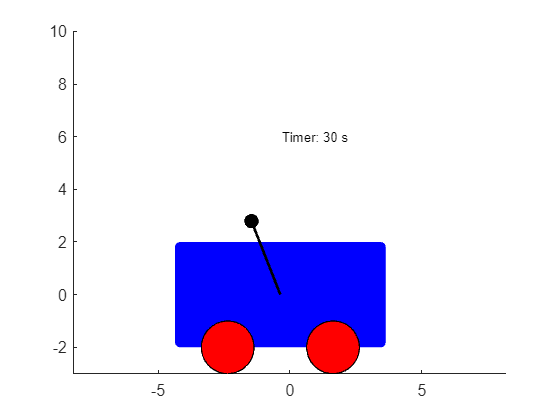

playAnimation(gcf, "AnimationRange",[1 numel(t_dwn)], 'FrameRate', 1);

save('LinearizedInvertedCartPend', 'A_dwn','B_dwn');